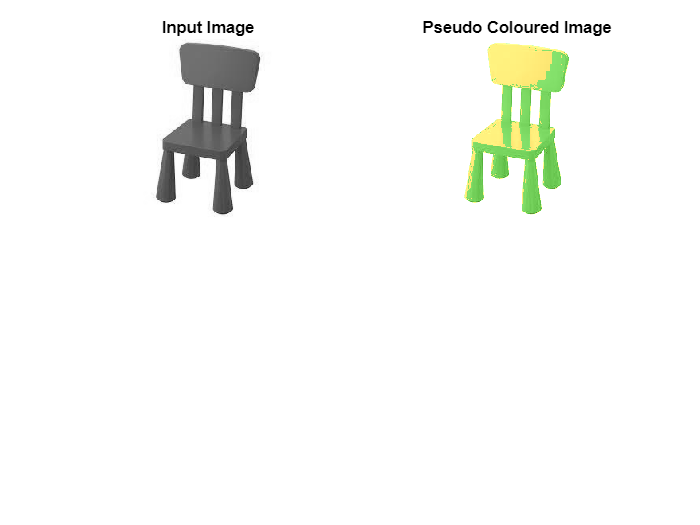

clc;
im=imread('original image.jpeg');
im=rgb2gray(im);

[m n]=size(im);
im=double(im);
for i=1:m
    for j=1:n
        if im(i,j)>=0 & im(i,j)<50
            output_image(i,j,1)=im(i,j)+50;
            output_image(i,j,2)=im(i,j)+100;
            output_image(i,j,3)=im(i,j)+10;
        end
        if im(i,j)>=50 & im(i,j)<100
            output_image(i,j,1)=im(i,j)+35;
            output_image(i,j,2)=im(i,j)+128;
            output_image(i,j,3)=im(i,j)+10;
        end
        if im(i,j)>=100 & im(i,j)<150
            output_image(i,j,1)=im(i,j)+152;
            output_image(i,j,2)=im(i,j)+130;
            output_image(i,j,3)=im(i,j)+15;
        end
        if im(i,j)>=150 & im(i,j)<200
            output_image(i,j,1)=im(i,j)+50;
            output_image(i,j,2)=im(i,j)+140;
            output_image(i,j,3)=im(i,j)+25;
        end
        if im(i,j)>=200 & im(i,j)<256
            output_image(i,j,1)=im(i,j)+120;
            output_image(i,j,2)=im(i,j)+160;
            output_image(i,j,3)=im(i,j)+45;
        end
    end
end
subplot(2,2,1);
imshow(uint8(im));
title('Input Image');

subplot(2,2,2);
imshow(uint8(output_image));
title('Pseudo Coloured Image');